# Define Styles Programmatically

This example shows how to define a set of styles programmatically. A style is a named set of formats. Styles allow you to define the appearance of report elements by specifying style names instead of defining all of the individual formats. Using styles can simplify the creation of report programs. The DOM API allows you to use styles that you define in a report template. Alternatively, as this example shows, you can define styles in a report program. Consider defining styles in a report program if you need or prefer to create a report program that does not require a template.

In this example, you generate a report that contains a table that summarizes the results of a sequence of tests. The example creates the test data. In a real-world application, you can implement the report program as a function that accepts the test data as one of its inputs. Here is the report generated by this example:

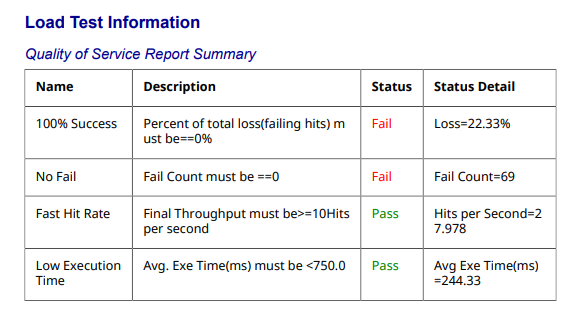

## Create Test Data

Create the test data as an array of structures.

test(1).Name = "100% Success";
test(1).Description = "Percent of total loss(failing hits) must be==0%";
test(1).Status = "Fail";
test(1).StatusDetail = "Loss=22.33%";

test(2).Name = "No Fail";
test(2).Description = "Fail Count must be ==0";
test(2).Status = "Fail";
test(2).StatusDetail = "Fail Count=69";

test(3).Name = "Fast Hit Rate";
test(3).Description = "Final Throughput must be>=10Hits per second";
test(3).Status = "Pass";
test(3).StatusDetail = "Hits per Second=27.978";

test(4).Name = "Low Execution Time";
test(4).Status = "Pass";
test(4).Description = "Avg. Exe Time(ms) must be <750.0";
test(4).StatusDetail = "Avg Exe Time(ms)=244.33";

## Import DOM API Package

Import the DOM API package so that you do not have to use fully qualified class names.

import mlreportgen.dom.*;

## Create a Document

To create a Microsoft® Word document, change the output type from `pdf `to `docx`. To create an HTML document, change `pdf` to `html` or `html-file`.

d = Document("report","pdf");

## Create a Container for the Styles

Create a [MATLAB map](https://www.mathworks.com/help/matlab/ref/containers.map.html) object to serve as a style sheet, that is, an object that maps style names to the set of formats that the styles contain.

styles = containers.Map;

## Define the Styles

This example uses a style for a top-level section heading style and a style for a subsection heading. First, create a style that defines the appearance common to both headings.

styles("baseHeadingPara") = {Color("darkblue"),FontFamily("Arial")};

Define a style for a paragraph that serves as a heading of a top-level report section. This style specifies an outline level of 1 so that the heading appears as a top-level entry in the report table of contents.

styles("heading1Para") = [styles("baseHeadingPara"),{OutlineLevel(1),Bold,...
                          FontSize("16pt")}];                              

Define a second level heading.

styles("heading2Para") = [styles("baseHeadingPara"),{OutlineLevel(2),...
                          OuterMargin("0in","0in","12pt","5pt"),Italic,FontSize("14pt")}];

Define the styles for a table, table header, and table entries.

styles("testSummaryTable") = {Border("solid"),RowSep("solid"),ColSep("solid"),Width("7in")};                          
styles("testSummaryTableHeader") = {Bold};
styles("testSummaryTableEntry") = {InnerMargin("10pt")};

Define the styles for the test status.

styles("passText") = {Color("green")};
styles("failText") = {Color("red")};

## Create the Report Content

Create the report title.

heading1Para = Paragraph("Load Test Information");
heading1Para.Style = styles("heading1Para");
append(d,heading1Para);

Create the test summary table description title.

heading2Para = Paragraph("Quality of Service Report Summary");
heading2Para.Style = styles("heading2Para");
append(d,heading2Para);

Create the test summary table header content. Define labels to display in the table header.

testSummaryTableHeader = ["Name","Description","Status","Status Detail"];  

Create a cell array to hold the content of the test summary table. The cell array is used later to create the table.

nTests = numel(test);
testSummaryTableBody = cell(nTests,4);

Store each item of the test data in a cell of the cell array. 

for t = 1:nTests
    testSummaryTableBody{t,1} = test(t).Name;
    testSummaryTableBody{t,2} = test(t).Description;
    result = test(t).Status;
    status = Paragraph(result);
     if result == "Pass"
         status.Style = styles("passText");
     else
         status.Style = styles("failText");
     end
       testSummaryTableBody{t,3} = status;
       testSummaryTableBody{t,4} = test(t).StatusDetail;
end

Create the test summary table.

testSummaryTable = FormalTable(testSummaryTableHeader,testSummaryTableBody);
testSummaryTable.Style = styles("testSummaryTable");
testSummaryTable.Header.Style = styles("testSummaryTableHeader");
testSummaryTable.TableEntriesStyle = styles("testSummaryTableEntry");

Append the test summary table to the document.

append(d,testSummaryTable);

## Close and View the Document

close(d);
rptview(d);

*Copyright 2020 The MathWorks, Inc.*